% Aaron Weinberg, Erin Richardson, Victoria Hurd
% EVA Informatics
% Apollo 12 2m Slope Data

% https://pds.lroc.asu.edu/data/LRO-L-LROC-5-RDR-V1.0/LROLRC_2001/DATA/SDP/NAC_DTM/APOLLO12/NAC_DTM_APOLLO12_README.TXT
% - Products are tied to LOLA elevations with RMS error of 1.31 m to 19.0 different LOLA orbit tracks.
%   The RMS error is the root-mean-square of the elevation difference between the LOLA points and the DTM. This value
%   is a combination of error from the LOLA points and the DTM, and may give a measure of the horizontal and vertical
%   accuracy of the DTM.
% - The reported precision error from SOCET SET is 0.8 m.
% - SOCET SET NGATE v5.5 was used to extract terrain.
% - Post spacing in DTM is 2.0 m.
% - DTM start time: 2010-02-05 10:34:26 and DTM stop time: 2010-02-05 12:28:05.
% - DTM extents:
%    Min. Lat.: -3.05226826
%    Min. Lon.: 336.45205417
%    Max. Lat.: -2.96217267
%    Max. Lon.: 336.61505963

%% Housekeeping
clear; clc;% close all

%% Load .mat
t = Tiff("./data_2m/NAC_DTM_APOLLO12.tiff",'r');

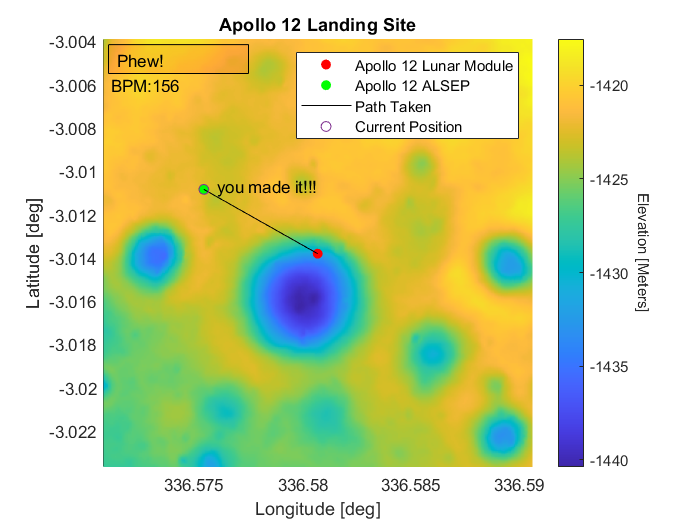

imageData = read(t);
imageData(imageData < -1000000000) = NaN; % out of bound data needs to be marked NaN

%% Constants
pixel_resolution = 2; % meters / pixel
minLat = -3.05226826;
maxLat = -2.96217267;
minLong = 336.45205417;
maxLong = 336.61505963;

LEMcoord = [360-23.41930,-3.01381]; % Using the Adjusted Coordinates https://history.nasa.gov/alsj/alsjcoords.html
ALSEPcoord = [360-23.42456,-3.01084]; % Using the Adjusted Coordinates https://history.nasa.gov/alsj/alsjcoords.html
% Numbering for each POI is from https://an.rsl.wustl.edu/apollo/mainnavsp.aspx?tab=map&m=A12
%coord12004 = [336.569,-3.00706]; % Measured by hand from figure 1 - Middle Crescent Crater
coord12055 = [336.573,-3.01233]; % Measured by hand from figure 1 - North Head Crater
coord12052 = [336.572,-3.01384]; % Measured by hand from figure 1 - West Head Crater
coord12040 = [336.570, -3.01938]; % Measured by hand from figure 1 - NW Bench Crater
coord12024 = [336.565,-3.0205]; % Measured by hand from figure 1 - E Sharp Crater
coord12041 = [336.571,-3.02024]; % Measured by hand from figure 1 - E Bench Crater
coordVec = [coord12055;coord12052;coord12040;coord12024;coord12041];

% the below are based on element numbers, not degrees
coord12055 = [384,530]; % Measured by hand from figure 1 - North Head Crater
coord12052 = [353,490]; % Measured by hand from figure 1 - West Head Crater
coord12040 = [341, 427]; % Measured by hand from figure 1 - NW Bench Crater
coord12024 = [275,387]; % Measured by hand from figure 1 - E Sharp Crater
coord12041 = [365,402]; % Measured by hand from figure 1 - E Bench Crater
coordVec = [coord12055;coord12024;coord12040;coord12052;coord12041];


%% Auto-Centering
% For dimensions centered around Apollo 12 LEM
Radius = 300; % meters - (temporary fix: decreased this from 5000 to 1000 to avoid NaNs that were present along the outsides of the map)
Height = Radius / pixel_resolution;
Width = Radius / pixel_resolution;

LatDelta = maxLat - minLat;
LongDelta = maxLong - minLong;

% LatDelta / length(imageData)
numLats = length(imageData(:,1));
numLongs = length(imageData(1,:));
latResolution = LatDelta/numLats;
LongResolution = LongDelta/numLongs;
%% Generate Meshgrid
% Generate axes
lat = maxLat:-latResolution:(minLat + latResolution);
long = minLong:LongResolution:(maxLong - LongResolution);

% find the index on our axes for the LEM
long_LEM_idx = interp1(long,1:length(long),LEMcoord(1),'nearest');
lat_LEM_idx = interp1(lat,1:length(lat),LEMcoord(2),'nearest');

X_start_idx = long_LEM_idx-Width;
X_end_idx = long_LEM_idx+Width;
Y_start_idx = lat_LEM_idx-Height;
Y_end_idx = lat_LEM_idx+Height;

% Protect for the axes window going out of bounds of our input file
if X_start_idx < 1
    X_start_idx = 1;
end
if Y_start_idx < 1
    Y_start_idx = 1;
end
if X_end_idx > length(long)
    X_end_idx = length(long);
end
if Y_end_idx > length(lat)
    Y_end_idx = length(lat);
end

% Generate Meshgrid and Z axis window
Z_elevation = imageData(Y_start_idx:Y_end_idx, X_start_idx:X_end_idx);
[Z_slope_X, Z_slope_Y] = gradient(Z_elevation); %get the x and y components of the gradient
Z_slope = atand(sqrt(Z_slope_X.^2 + Z_slope_Y.^2)); % get the normalized gradient and take the arc tan to get degrees
[X,Y] = meshgrid(long(X_start_idx:X_end_idx),lat(Y_start_idx:Y_end_idx));

%% View
% Plotting Elevation
figure
hold on 
h = surf(X, Y, Z_elevation);
set(h,'LineStyle','none')
h.Annotation.LegendInformation.IconDisplayStyle = 'off';
title("Apollo 12 Landing Site")
xlabel("Longitude [deg]")
ylabel("Latitude [deg]")
axis equal
axis tight
c = colorbar;
c.Label.String = "Elevation [Meters]";
c.Label.Rotation = 270;
c.Label.VerticalAlignment = "bottom";
view(2)
scatter(LEMcoord(1),LEMcoord(2),"filled","red")
scatter(ALSEPcoord(1),ALSEPcoord(2),"filled","green")


%real time aspect
Startcoord = [360-23.41930,-3.01381];
Endcoord = [360-23.42456,-3.01084];
N = 100;
X_pos=linspace(Startcoord(1),Endcoord(1),N)';
Y_pos=linspace(Startcoord(2),Endcoord(2),N)';

Heart_rate = normrnd(110, 5, N, 1);

for h = 1:N
    Heart_rate(h) = round(Heart_rate(h) + h/2);
end

X_path = [X_pos(1)];
Y_path = [Y_pos(1)];
path_plot = plot(X_path,Y_path, "black");
path_plot.XDataSource = 'X_path';
path_plot.YDataSource = 'Y_path';

X_current = X_pos(1);
Y_current = Y_pos(1);
current_pos = scatter(X_path,Y_path);
current_pos.XDataSource = 'X_current';
current_pos.YDataSource = 'Y_current';

legend("Apollo 12 Lunar Module", "Apollo 12 ALSEP", "Path Taken", "Current Position")
txt_marker = text(X_current,Y_current,'');

txt_alert = annotation("textbox");
txt_alert.Position= [.155 .86 .2 .055];
txt_alert.EdgeColor = 'none';
txt_alert.BackgroundColor = 'red';
txt_alert.FaceAlpha = 0.0;

BPM_alert = text(long(X_start_idx + 5),lat(Y_start_idx + 32),'');

for i = 2:N
    X_path(i) = X_pos(i);
    Y_path(i) = Y_pos(i);
    X_current = X_pos(i);
    Y_current = Y_pos(i);
    BPM_alert.String = strcat('BPM: ',string(Heart_rate(i))); 
    
    
    if i > 20 
        txt_marker.String = 'you';
        txt_marker.Position = [X_current + .0006, Y_current + .00015];
    end
        
    if i == 40
        txt_alert.String = 'Physio Alert 1!!!!';
        txt_alert.FaceAlpha = 0.2;
    end
    
    if i == 60
        txt_alert.String = 'Different Alert!';
        txt_alert.FaceAlpha = 0.4;
    end    
    
    if i > 80
        txt_alert.String = 'Certain Doom!';
        txt_alert.FaceAlpha = 0.5;
        
        if mod(i,2) == 1
            txt_alert.FaceAlpha = 0.9;
        end
    end  
    
    if i == N
        txt_marker.String = 'you made it!!!';
        txt_alert.String = 'Phew!';
        txt_alert.EdgeColor = 'black';
        txt_alert.FaceAlpha = 0.1;
    end
    
    refreshdata
    drawnow
end

hold off


% Plotting Slope
% figure
% hold on 
% scatter(LEMcoord(1),LEMcoord(2),"filled","red")
% scatter(ALSEPcoord(1),ALSEPcoord(2),"filled","blue")
% legend("Apollo 12 Lunar Module", "Apollo 12 ALSEP")
% h = surf(X, Y, Z_slope);
% set(h,'LineStyle','none')
% h.Annotation.LegendInformation.IconDisplayStyle = 'off';
% title("Apollo 12 Landing Site")
% xlabel("Longitude [deg]")
% ylabel("Latitude [deg]")
% axis equal
% axis tight
% colormap turbo
% c = colorbar;
% c.Label.String = "Slope [deg]";
% c.Label.Rotation = 270;
% c.Label.VerticalAlignment = "bottom";
% view(2)
% hold off
